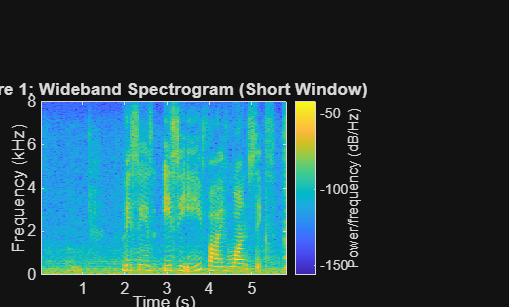

% Experiential DSP Assignment 9

% Reading the file
[y, Fs] = audioread('ece516.wav');

% Setting nfft Size
nfft = 1024;

% Setting window length
win_len_ms = 100;

% Compute number of samples
win_len_samp = round(win_len_ms * Fs / 1000);

% Designing the window
win = hamming(win_len_samp);

% Number of overlapping samples
noverlap = round (win_len_samp * 0.5);

% Plotting wide band spectrogram
figure(1)
spectrogram (y, win, noverlap, nfft, Fs, 'yaxis')
title('Figure 1: Wideband Spectrogram (Short Window)');

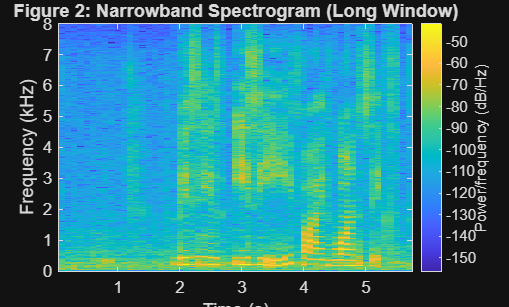

% Step 9 but with win_len_ms = 200
% Setting window length
win_len_ms_2 = 200;

% Compute number of samples
win_len_samp_2 = round(win_len_ms_2 * Fs / 1000);

% Designing the window
win_2 = hamming(win_len_samp_2);

% Number of overlapping samples
noverlap_2 = round (win_len_samp_2 * 0.5);

% Plotting wide band spectrogram
figure(2)
spectrogram (y, win_2, noverlap_2, nfft, Fs, 'yaxis')
title('Figure 2: Narrowband Spectrogram (Long Window)');

%{
The wide band spectrogram (short window) has sharper vertical lines compared to the narrowband spectrogram (long window)
The frequency resolution is clearer on the narrowband than the wide band
spectrogram.
%}
